% 1. Read and resize images.

image1 = imread("_bottle.jpg");
image2 = imread("_penHolder.jpg");

% Image1 is on its side if not rotated
image1 = imrotate(image1, 270);

image1 = imresize(image1, [500 500]);
image2 = imresize(image2, [500 500]);

% Now change them to double and grey
image1 = rgb2gray(im2double(image1));
image2 = rgb2gray(im2double(image2));

% Save images
LP = image1;
HP = image2;

imwrite(LP,"LP.png");
imwrite(HP,"HP.png");

% 2. Compute Frequency Representations
LPFreq = fft2(LP);
HPFreq = fft2(HP);

% Save files
imwrite( fftshift(abs(LPFreq))/50, "LP-freq.png" );
imwrite( fftshift(abs(HPFreq))/50, "HP-freq.png" );

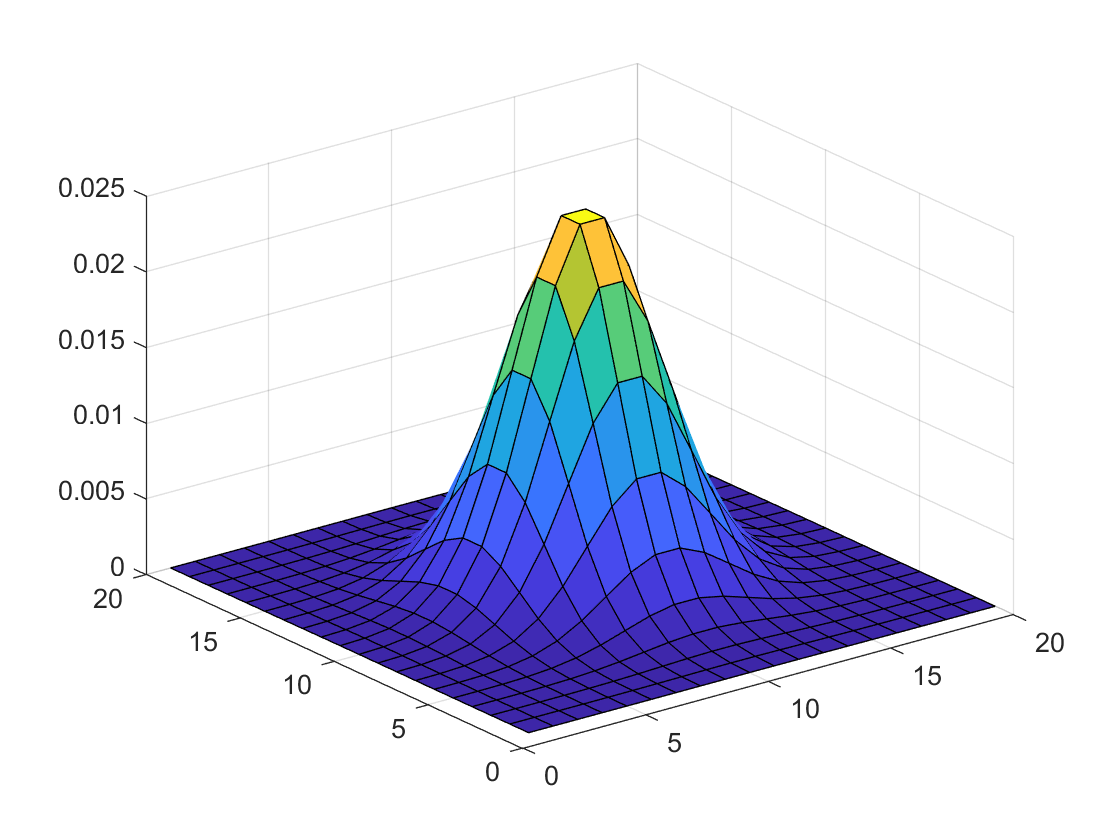

% 3. Visualize kernels

% Make kernals and save their surfaces
sobx  = [-1, 0, 1; -2, 0, 2; -1, 0, 1];
gauss = fspecial('gaussian', 20, 2.5);
dogx  = conv2(gauss, sobx);

saveas(surf(gauss), "gaus-surf.png")

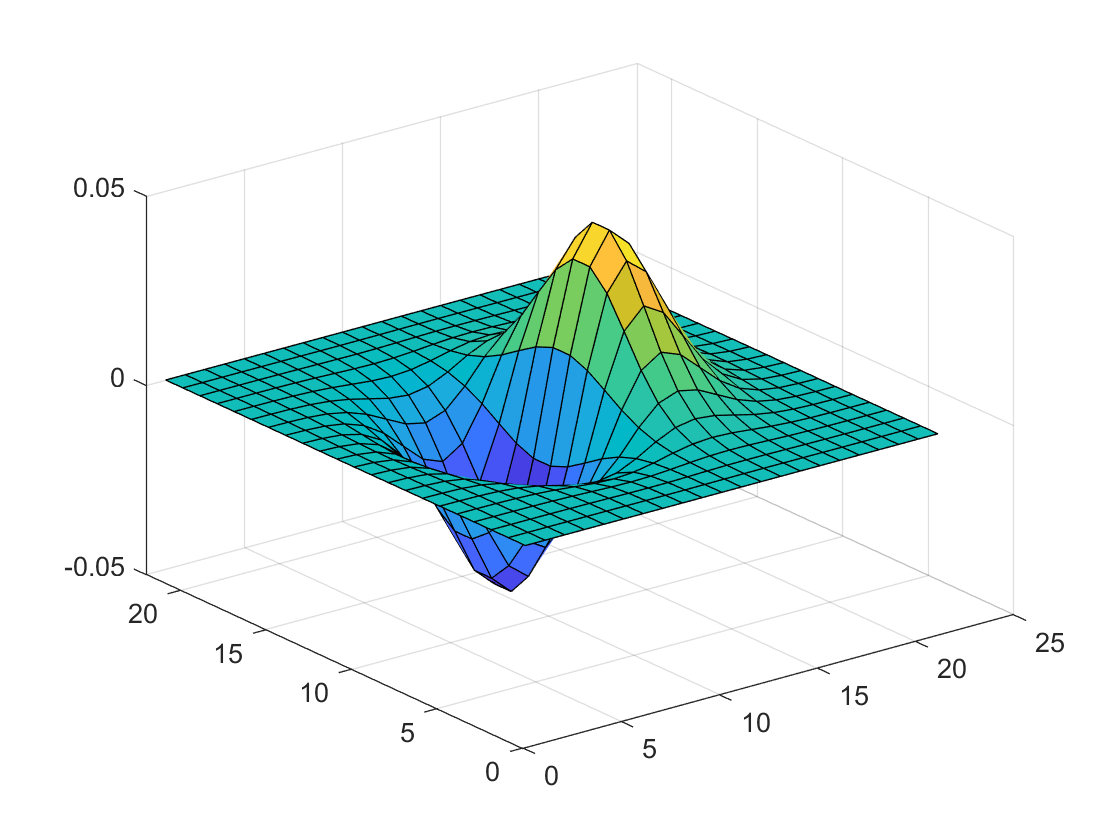

saveas(surf(dogx), "dog-surf.png")


% Apply gaussian filter to images
gaussLP = imfilter(LP, gauss);
gaussHP = imfilter(HP, gauss);

% Get frequency domain of images
gaussLPfft = fft2(gaussLP);
gaussHPfft = fft2(gaussHP);

% Save images
imwrite(gaussLP, "LP-filt.png");
imwrite(gaussHP, "HP-filt.png");
imwrite(fftshift(abs(gaussLPfft)), "LP-filt-freq.png");
imwrite(fftshift(abs(gaussHPfft)), "HP-filt-freq.png");

% Compute Fourier Transform of DoG kernal
dogFFT = fft2(dogx, 500, 500);

% Apply DoG ft filter to the images in the f domain and use the inverse
% transform to change them back to the spatial domain
LPDogFiltFreq = dogFFT .* LPFreq;
HPDogFiltFreq = dogFFT .* HPFreq;

LPDogFilt = ifft2(LPDogFiltFreq);
HPDogFilt = ifft2(HPDogFiltFreq);

% Save images, make spatial domain easier to see
imwrite(LPDogFilt*2, "LP-dogfilt.png")
imwrite(HPDogFilt*2, "HP-dogfilt.png")
imwrite(fftshift(abs(LPDogFiltFreq)), "LP-dogfilt-freq.png")
imwrite(fftshift(abs(HPDogFiltFreq)), "HP-dogfilt-freq.png")

% 4. Anti-aliasing
LP2 = LP(1:2:end, 1:2:end);
HP2 = HP(1:2:end, 1:2:end);
LP4 = LP(1:4:end, 1:4:end);
HP4 = HP(1:4:end, 1:4:end);

LP2fft = fft2(LP2);
HP2fft = fft2(HP2);
LP4fft = fft2(LP4);
HP4fft = fft2(HP4);

% imshow([LP4 HP4; fftshift(abs(LP4fft))/50 fftshift(abs(HP4fft))/50] )

% Save all the images
imwrite(LP2, "LP-sub2.png");
imwrite(HP2, "HP-sub2.png");
imwrite(LP4, "LP-sub4.png");
imwrite(HP4, "HP-sub4.png");
imwrite( fftshift(abs(LP2fft))/50, "LP-sub2-freq.png" );
imwrite( fftshift(abs(HP2fft))/50, "HP-sub2-freq.png" );
imwrite( fftshift(abs(LP4fft))/50, "LP-sub4-freq.png" );
imwrite( fftshift(abs(HP4fft))/50, "HP-sub4-freq.png" );

% Create anti-aliasing filters
antiAliFilter2 = fspecial('gaussian', 7, 1.5);
antiAliFilter4 = fspecial('gaussian', 5, 2);

% Apply aa filter before converting to frequency domain
HP2aa = imfilter(HP2, antiAliFilter2);
HP4aa = imfilter(HP4, antiAliFilter4);

% Convert images to frequency domain
HP2aafft = fft2(HP2aa);
HP4aafft = fft2(HP4aa);

% Save all images
imwrite(HP2aa, "HP-sub2-aa.png")
imwrite(HP4aa, "HP-sub4-aa.png")
imwrite(fftshift(abs(HP2aafft))/50, "HP-sub2-aa-freq.png")
imwrite(fftshift(abs(HP4aafft))/50, "HP-sub4-aa-freq.png")

% 5. Canny Edge Detection

% Manually selected the following thresholds
LPLowLow   = [0.01 0.07];
LPLowHigh  = [0.06 0.07];
LPHighLow  = [0.03 0.05];
LPHighHigh = [0.03 0.09];
LPOptimal  = [0.03 0.07];

HPLowLow   = [0.01 0.07];
HPLowHigh  = [0.06 0.07];
HPHighLow  = [0.04 0.05];
HPHighHigh = [0.04 0.09]; 
HPOptimal  = [0.04 0.07];

% Save images
imwrite(edge(LP, 'canny', LPLowLow), "LP-canny-lowlow.png");
imwrite(edge(LP, 'canny', LPLowHigh), "LP-canny-lowhigh.png");
imwrite(edge(LP, 'canny', LPHighLow), "LP-canny-highlow.png");
imwrite(edge(LP, 'canny', LPHighHigh), "LP-canny-highhigh.png");
imwrite(edge(LP, 'canny', LPOptimal), "LP-canny-optimal.png");

imwrite(edge(HP, 'canny', HPLowLow), "HP-canny-lowlow.png");
imwrite(edge(HP, 'canny', HPLowHigh), "HP-canny-lowhigh.png");
imwrite(edge(HP, 'canny', HPHighLow), "HP-canny-highlow.png");
imwrite(edge(HP, 'canny', HPHighHigh), "HP-canny-highhigh.png");
imwrite(edge(HP, 'canny', HPOptimal), "HP-canny-optimal.png");